## Week 7 Workshop: Analysing the main sequence

Today we will start analyzing our own eye movement data! We'll start by exploring what's known as the *main sequence. *Since the 1960s, its been observed that there is a highly stereotyped relationship between the duration, amplitude, and peak velocity of the eye movement. Borrowing a term from astronomy, Bahill and colleagues defined this relation as the *main sequence* for saccadic eye movements (Bahill et al., [1975](https://doi.org/10.1016/0025-5564(75)90075-9)). Deviations of eye movements from the main sequence can be used as markers of specific neurological disorders. 

We'll also start analysing data from more than one patricipant. Here, I'll use two of the sample datasets, but you can edit this to match the members of your group.

% list of subjects
subjects = {'RR', 'AE'}; % edit this cell array to include the members of your group!

% assign a color for each subject
subject_colors = {'#ca0020','#0571b0'}; % HEX values, could also be RGB triplets

Matlab will accept colors as HEX strings (like above) or RGB triplets. There are also some built in matlab colors that can be input as strings, but they're pretty awful. I would suggest using a site like [colorbrewer](https://colorbrewer2.org/#type=sequential&scheme=BuGn&n=3) to choose a range of colors for your group. This site has useful features like helping you choose colorblind-safe color schemes. Note: if you use RGB triplets in matlab they need to be normlaized to a scale from 0 to 1. Often RGB triplets are expressed in values up to 255. For example, the colorbrewer triplet for the first color shown above is: 202,0,32. To use this matlab: 

`mycolor = [202, 0, 32]./255;`

Now lets load up the data!

We'll use a `for` loop to load up the data for each subject. We'll be using loops a lot going forward, its a handy way to perform the same analysis on each subject. 

Here, we can load up the data for all the subjects. We'll create a new structure variable `teamdata` to store all of the information from the individual variables `data` that are saved in each mat file. Make sure you've downloaded the data from all participants, and navigate to the folder where the data is stored.

for i = 1:numel(subjects) % loop through each subject
    subject = subjects{i};
    filename = [subject '.utimages.export.mat'];
    load(filename)
    
    teamdata.(subject) = data.(subject);
    clear data
end

Great! Now we a have a giant structure variable with all our data in it.

## Plotting the main sequence

We'll be dealing with three main variables today: the peak velocity, the amplitude, and the duration of the saccade. First, we'll look at the variables individually and see how they compare across subjects. For each of the three variables, we'll plot a histogram for each subject. We can also do some stats to compare across subjects.

We'll use Matlab's `subplot `function to plot a multipaneled figure. Each row will be a different subject and each column a different variable: Peak velocity, amplitude, and duration. For each panel, we'll use matlab's `histogram` function to view the data.

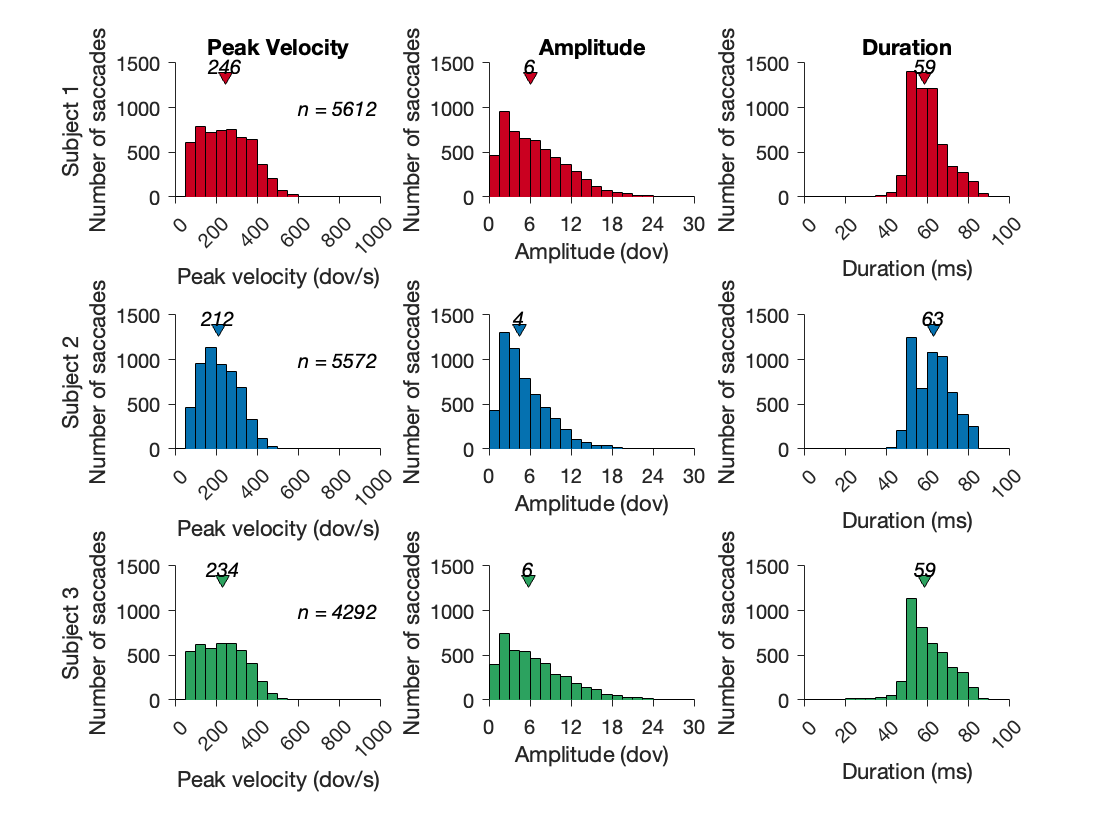

panelind = 0;

figure;
for i = 1:numel(subjects) % loop through each subject
    subject = subjects{i};
    
    % first, let's get rid of saccades that include NaNs
    % also microsaccades (saccades < 1 deg amplitude)
    vel = [teamdata.(subject).saccades(:).peakvel]; 
    peakvel = vel(1,:); % Note: first row is peak velocity, second row is time point of peak velocity
    amp = [teamdata.(subject).saccades(:).amplitude]; 
    dur = [teamdata.(subject).saccades(:).duration]; 
    
    nind = ~isnan(peakvel) & ~isnan(amp) & ~isnan(dur) & amp > 1; 
    peakvel = peakvel(nind); amp = amp(nind); dur = dur(nind);
   
    % Plot peak velocity
    panelind = panelind + 1;
    subplot(numel(subjects),3,panelind),  hold on; 
    histogram(peakvel,0:50:1000,'FaceColor',subject_colors{i},'FaceAlpha',1)
    
    % plot the median on the graph
    plot(median(peakvel),1500*0.9,'v','Color',[0 0 0],'MarkerFaceColor',subject_colors{i},'MarkerSize',6)
    text(median(peakvel),1500*0.98,num2str(median(peakvel),3),'FontName', 'Helvetica', 'FontAngle','italic','FontSize',10,'HorizontalAlignment',"center");
    
    % plot number of saccades on the graph
    text(600, 1000,['n = ' num2str(numel(peakvel))],'FontName', 'Helvetica', 'FontAngle','italic','FontSize',10);
    
    % make axes look neat
    set(gca,'XTick', 0:200:1000);
    set(gca,'YTick',  0:500:1500);
    set(gca,'FontName', 'Helvetica', 'FontAngle','normal','FontSize',10);
    set(gca,'TickDir', 'out');
    set(gca,'TickLength', [0.03,0.035]);
    xlabel('Peak velocity (dov/s)')
    ylabel({['Subject ' num2str(i)] 'Number of saccades'})
    if i == 1 % only put a title on the top row
    title('Peak Velocity')
    end
    axis([0 1000 0 1500])
    box off
    
    % Plot amplitude
    panelind = panelind + 1;
    subplot(numel(subjects),3,panelind), hold on;
    histogram(amp,0:1.5:30,'FaceColor',subject_colors{i},'FaceAlpha',1)
    
    % plot the median on the graph
    plot(median(amp),1500*0.9,'v','Color',[0 0 0],'MarkerFaceColor',subject_colors{i},'MarkerSize',6)
    text(median(amp),1500*0.98,num2str(median(amp),1),'FontName', 'Helvetica', 'FontAngle','italic','FontSize',10,'HorizontalAlignment',"center");
    
    % make axes look neat
    set(gca,'XTick', 0:6:30);
    set(gca,'YTick',  0:500:1500);
    set(gca,'FontName', 'Helvetica', 'FontAngle','normal','FontSize',10);
    set(gca,'TickDir', 'out');
    set(gca,'TickLength', [0.03,0.035]);
    xlabel('Amplitude (dov)')
    ylabel('Number of saccades')
    if i == 1 % only put a title on the top row
    title('Amplitude')
    end
    axis([0 30 0 1500])
    box off
    
    % Plot duration
    panelind = panelind + 1;
    subplot(numel(subjects),3,panelind), hold on;
    histogram(dur,0:5:100,'FaceColor',subject_colors{i},'FaceAlpha',1)
    
    % plot the median on the graph
    plot(median(dur),1500*0.9,'v','Color',[0 0 0],'MarkerFaceColor',subject_colors{i},'MarkerSize',6)
    text(median(dur),1500*0.98,num2str(median(dur),3),'FontName', 'Helvetica', 'FontAngle','italic','FontSize',10,'HorizontalAlignment',"center");
    
    % make axes look neat
    set(gca,'XTick', 0:20:100);
    set(gca,'YTick',  0:500:1500);
    set(gca,'FontName', 'Helvetica', 'FontAngle','normal','FontSize',10);
    set(gca,'TickDir', 'out');
    set(gca,'TickLength', [0.03,0.035]);
    xlabel('Duration (ms)')
    ylabel('Number of saccades')
    if i == 1 % only put a title on the top row
    title('Duration')
    end
    axis([0 100 0 1500])
    box off
    
end

Now let's look at the relationship betwen these two variables. Peak velocity and amplitude tend to be linearly related for smaller amplitudes, but that that realtionship flattens out for higher amplitude saccades. So we can try to fit that relationship with an exponential function. Amplitude and duration tend to be linearly realted.  So we can fit that data with a straight line.

To fit the data, we're going to be using matlab's `polyfit` and `polyval `fucntions. We'll use the `scatter` function to plot the raw data.

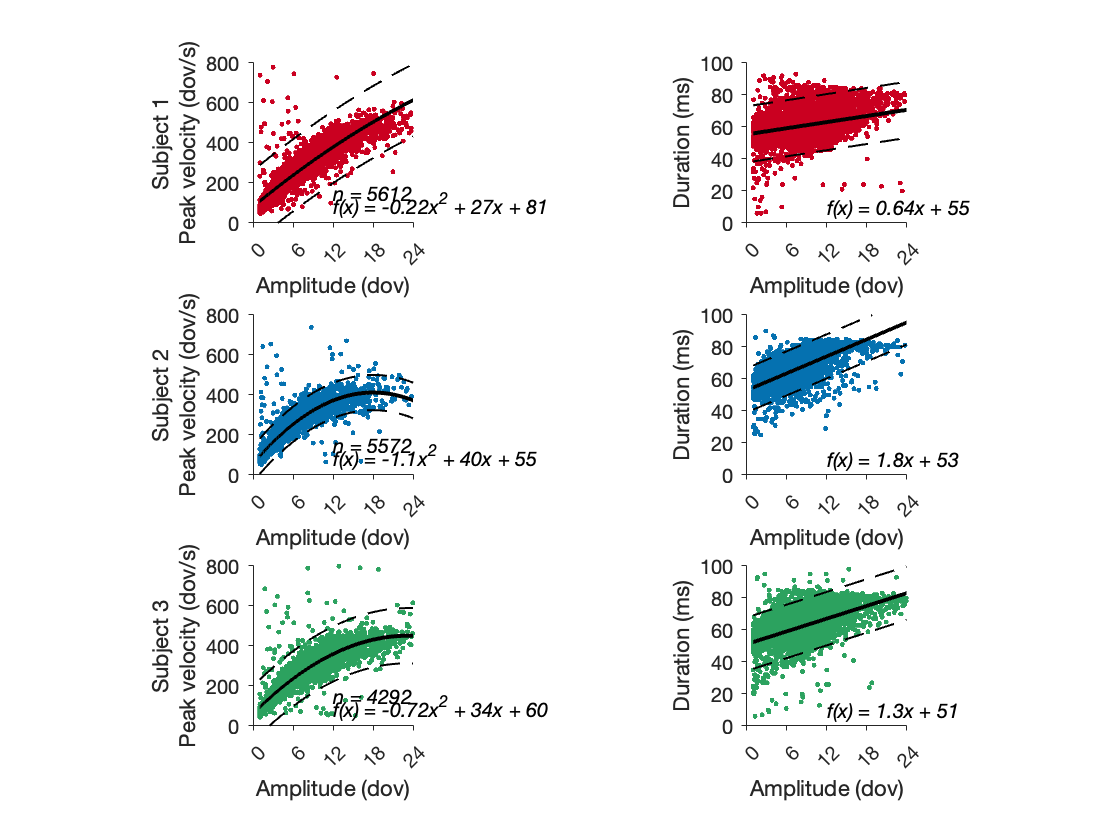

panelind = 0;

figure;
for i = 1:numel(subjects) % loop through each subject
    subject = subjects{i};
    
    % first, let's get rid of saccades that include NaNs
    % also microsaccades (saccades < 1 deg amplitude)
    vel = [teamdata.(subject).saccades(:).peakvel]; 
    peakvel = vel(1,:); % Note: first row is peak velocity, second row is time point of peak velocity
    amp = [teamdata.(subject).saccades(:).amplitude]; 
    dur = [teamdata.(subject).saccades(:).duration]; 
    
    nind = ~isnan(peakvel) & ~isnan(amp) & ~isnan(dur) & amp > 1; 
    peakvel = peakvel(nind); amp = amp(nind); dur = dur(nind);
    
    % Peak velocity vs amplitude
    panelind = panelind + 1;
    subplot(numel(subjects),2,panelind),  hold on; 
    plot(amp,peakvel,'.','Color',subject_colors{i})
    
    % use polyfit to fit an exponential function to the data
    [p,S] = polyfit(amp,peakvel,2);
    x = sort(amp,'ascend');
    [f, delta] = polyval(p,x,S);
    
    plot(x,f,'-','Color',[0 0 0],'LineWidth',2) % plot least squares fit
    plot(x,f+2*delta, '--','Color',[0 0 0],'LineWidth',1) % plot 95% confidence inteverals
    plot(x,f-2*delta, '--','Color',[0 0 0],'LineWidth',1) 
    
    % legend
    text(12, 150,['n = ' num2str(numel(peakvel))],'FontName', 'Helvetica', 'FontAngle','italic','FontSize',10);
    text(12,100,['f(x) = ' num2str(p(1),2) 'x^2 + ' num2str(p(2),2) 'x + ' num2str(p(3),2)], 'FontName', 'Helvetica', 'FontAngle','italic','FontSize',10);
    
    % make axes look neat
    set(gca,'XTick', 0:6:30);
    set(gca,'YTick',  0:200:1000);
    set(gca,'FontName', 'Helvetica', 'FontAngle','normal','FontSize',10);
    set(gca,'TickDir', 'out');
    set(gca,'TickLength', [0.03,0.035]);
    xlabel('Amplitude (dov)')
    ylabel({['Subject ' num2str(i)] 'Peak velocity (dov/s)'})
    axis([0 24 0 800])
    box off
    axis square
    
    % Plot amplitude vs duration
    panelind = panelind + 1;
    subplot(numel(subjects),2,panelind),  hold on; 
    plot(amp,dur,'.','Color',subject_colors{i})
    
    % use polyfit to fit an linear function to the data
    [p, S] = polyfit(amp,dur,1);
    x = sort(amp,'ascend');
    [f, delta] = polyval(p,x,S);
    
    plot(x,f,'-','Color',[0 0 0],'LineWidth',2) % plot least squares fit
    plot(x,f+2*delta,'--','Color',[0 0 0],'LineWidth',1) % plot 95% confidience interval
    plot(x,f-2*delta,'--','Color',[0 0 0],'LineWidth',1) 
    
    % legend
    text(12,10,['f(x) = ' num2str(p(1),2) 'x + ' num2str(p(2),2)], 'FontName', 'Helvetica', 'FontAngle','italic','FontSize',10);
    
    % make axes look neat
    set(gca,'XTick', 0:6:30);
    set(gca,'YTick',  0:20:100);
    set(gca,'FontName', 'Helvetica', 'FontAngle','normal','FontSize',10);
    set(gca,'TickDir', 'out');
    set(gca,'TickLength', [0.03,0.035]);
    xlabel('Amplitude (dov)')
    ylabel('Duration (ms)')
    axis([0 24 0 100])
    box off
    axis square
   
end

### Exercises

- Can you think of other statistics that would be useful to your resuts? A table of your the fit vaules? How well does the fit caputre the data? Can you calculate the root mean squared error? Or a correlation coefficient? Hint: there are built in matlab functions that will do this for you. Try searching to documentation.

- Can you plot the fits/confidence intevals for the whole group on one axes? Are they overlapping?

Now is also a good time to start preparing figures for your poster presenatations. Either in this script, or in a new m-file, can you start getting figures ready for your poster?

- Save Figures in a file format like png of tiff

- Edit figure sizes and text to be appropriate to the size of your posters (minimum fonts on posters should probably be around 28 pt). Hint: check the documentation on `figure `to see how you can set the size of the figure.